clear; clc;
format long;
data = csvread('data.csv', 1, 0);

hold on;
scatter(data(:,1), data(:,2));
label0 = 'csv-data';
hold off;

% target fuction
fx_target = @(x) -0.2805016493803706*x^2 + 2.8400814288686433*x + 2.140542066628967;

hold on;
plot1 = fplot(fx_target, [0, 10], 'LineWidth',2); 

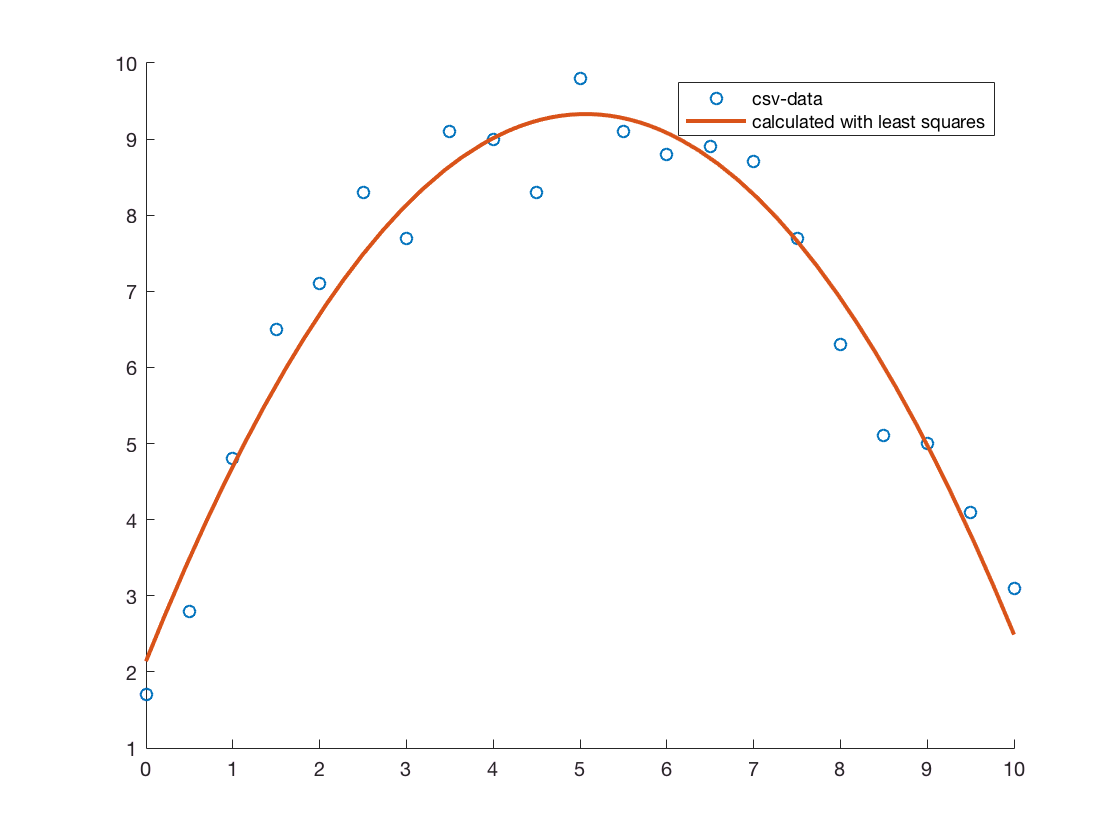

label1 = 'calculated with least squares';
hold off;

legend(label0, label1)